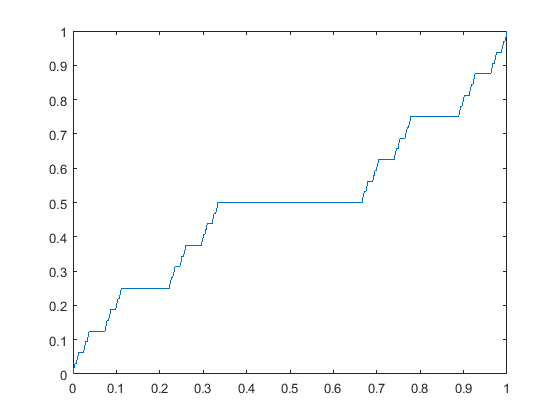

x6 = 0:0.001:1;
n = 8;
y6 = cantor(x6, n);


plot(x6, y6);

function s = cantor(x,n)

%assert(n>0 && round(n)==n , 'The n must be a positive integer')

for k = 1:numel(x)
    s(k) = cantor_aux(x(k),n);
end
end

function s = cantor_aux(x,n)

if n == 0
    s=x;
elseif x <= 1/3
    s = 1/2*cantor_aux(3*x,n-1);
elseif  x <= 2/3
    s = 1/2;
else s = 1/2+1/2*cantor_aux(3*x-2,n-1);
end
end